# REDES NEURONALES: UN EJEMPLO PARA CLASIFICACIÓN.

# Introducción

Como hemos visto, las redes neuronales pueden usarse como "regresores" o "clasificadores". Vamos a desarrollar un ejemplo enfocado a la clasificación.

Antes de lanzarse a enfrentar un problema donde se trabaje con datos, es importante conocer bien el problema que se está trabajando. Esto implica familiarizarse con el conjunto de datos, la naturaleza de la problemática, los objetivos que se quieren alcanzar, etc.

Hemos usado un conjunto de datos bastante usual en este ámbito:  los datos de la flor Iris. Se trata de un conjunto de datos que contiene información de tres subespecies de la flor Iris: "Setosa", "Versicolor", "Virgínica" . Esta información se expresa a través de cuatro características de la misma flor (medidas en cm ): "largo del sèpalo", "ancho del sépalo", "largo del pétalo", "ancho del pétalo". El objetivo será poder averiguar la subespecie de la flor,  al observar estas cuatro características. El conjunto de datos total tienen 50 mediciones, lo cual representa una cantidad poco significativa, pero nos servirá como ejemplo.

Por otro lado, el motivo de que este conjunto de datos sea usual en este ámbito puede ser debido a que fue usado por Ronald Fisher (considerado por muchos, el padre de la estadística moderna) en su publicación sobre discriminantes lineales : "*The use of multiple measurements in taxonomic problems*".

Si quieres saber más puedes consultar los siguientes enlaces:

1) Enlace al conjunto de datos

[https://en.wikipedia.org/wiki/Iris_flower_data_set](https://en.wikipedia.org/wiki/Iris_flower_data_set)

2) Enlace al paper original:  "*The use of multiple measurements in taxonomic problems*"

[http://rcs.chemometrics.ru/Tutorials/classification/Fisher.pdf](http://rcs.chemometrics.ru/Tutorials/classification/Fisher.pdf)

[](https://es.wikipedia.org/wiki/Iris_flor_conjunto_de_datos)

# 1) Carga de los datos de flores Iris obtenidos por Ronald Fisher

Primero se cargan los datos en el espacio de trabajo de Matlab, ejecutando la siguiente instrucción en la ventana de comandos.

carga_datos_visualizacion

**Comprueba que tras ejecutar esta istrucción, aparecerán en el espacio de trabajo las variables 'caracteristicas'  y 'clasificacion' . **

**¿Qué información contiene la variable: 'caracteristicas'?¿Que información contiene la variable 'clasificacion? ¿Es importante tenerlas en variables separadas?**

*(ESCRIBE TU RESPUESTA AQUI)*

# 2) Visualización de los datos: ¿De qué manera podemos clasificar visualmente los datos en base a las características?

A continuación vamos a visualizar los datos. Debido a que los datos son multivariantes, necesitaremos varios gráfcos para poder enfrentar todas las características , una a una. Observa que la diagonal principal muestra el eje que representa a la característica.

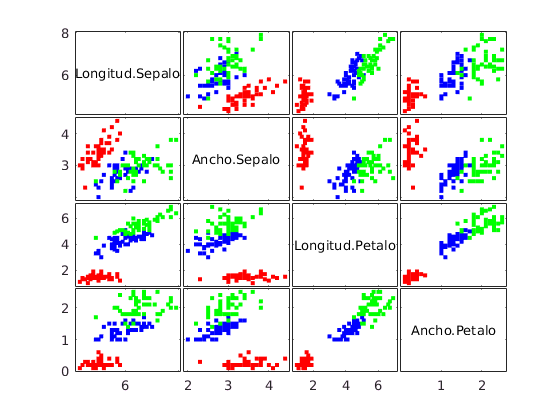

figure(1)
gplotmatrix(caracteristicas, [], clasificacion, ['r', 'b', 'g'],[],[],'off','variable',{'Longitud.Sepalo','Ancho.Sepalo','Longitud.Petalo','Ancho.Petalo'}); % Hacemos un plot enfrentando a todas las características


**¿Que flor tiene la longitud del pétalo más pequeño? ¿y la el áncho del pétalo más ancho?**

**¿Que flor es la más fácil de clasificar? Justifica tu respuesta.**

## *(ESCRIBE TU RESPUESTA AQUI)*

# 3) Creación y entrenamiento de la red neuronal para clasificación de flores Iris

En la sección anterior nos familiarizamos con los datos. Hemos visto que los objetos del mundo real pueden ser representados por características que los definen. Además estos objetos del mundo real los dividimos en clases. Recordamos los conceptos importantes:

- Número de capas ocultas: Es el número de capas de neuronas ocultas. En este cómputo no cuenta la capa de entrada ni la capa de salida.

- Número de neuronas por capa: Es el número de neuronas que tiene cada capa.  *Ejemplo:  Si definimos: hiddenLayers=[2, 10, 5] , estaremos representando una red con 3 capas, donde tiene 2 neuronas en la primera capa, 10 en la segunda, 5 en la tercera.*

- Número de neuronas a la salida: Es el número de neuronas a la salida de la red. Este debe de coincidir con el número de clases del problema.

- learning rate: Es el ratio de avance a la hora de descender por la función de périda.

- epochs: Es el número de veces que se recorrerá el dataset de forma completa. Cuando se indica este número, se está poniendo un tope. *Ejemplo: epochs = 100. Significa que como máximo la red neuronal debe entrentar durante 100 epochs.*

## 3.1) Definición de la red

A continuación vamos a construir nuestra primera red neuronal. Como verás es muy sencillo. Simplemente hay que definir la arquitectura y los parámetros que la definen.

% 1) Seleccionamos los parametros.
hiddenLayers=[1]; % Especificamos la arquitectura del modelo
learning_rate=0.1; % Especificamos el ratio de aprendizaje
epochs=500; % Especificamos el numero maximo de epochs

% 2) Construimos la red con los parametros que acabamos de definir
red = define_red(hiddenLayers,learning_rate,epochs);
view(red);

**Cambia tú mismo la arquitectura. Define una red de una sola capa oculta, con 3 neuronas a cada capa. Define un learning rate de 0.1. Como máximo debería de haber 500 epochs.**

## 3.2) Entrenamiento de la red

A continuación volvemos a cargar los datos. Aunque ya lo hayamos realizado más arriba, lo volvemos a hacer, ya que los datos de arriba estaba estructurados para que su representación fuera sencilla. Estos que estamos cargando ahora, están estructurados para que sea fácil entrenar una red con ellos. Una vez los tenemos cargados los introducimos en la función "entrena_red". Fíjate que a esta función le introducimo la información de la arquitectura de la red a través de la variable "red", las características a través de la variable "características" y las clases a través de la variable "clasificación".

carga_datos_entrenamiento; 
[red_entrenada,info_entrenamiento] = entrena_red(red,caracteristicas,clasificacion);

## 3.3) Usamos la red para clasificar.

¡ Enhorabuena !, ya tienes tu red entrenada. Ahora bien, ¿cómo puedes saber si la red funciona bien? ¿cómo puedes medir la calidad predictiva de la red?

caracteristicas_test=caracteristicas(:,info_entrenamiento.testInd);
clasificacion_test=clasificacion(:,info_entrenamiento.testInd);
clasificacion_test_red=red_entrenada(caracteristicas_test);
performance = perform(red_entrenada,clasificacion_test,clasificacion_test_red);
precision=evalua_red(clasificacion_test,clasificacion_test_red);

accuracy = 95.6522

¿Cuá es el significado de este valor de precisión?

## 3.4) Visualización de la función de pérdida

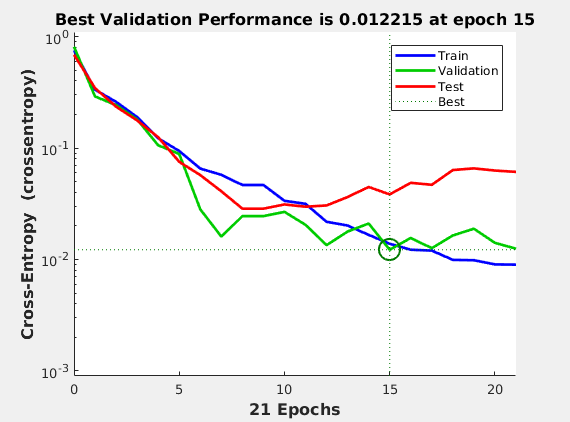

figure(2), plotperform(info_entrenamiento)

¿Qué ocurre cuando el entrenamiento alcanza el óptimo de validación?

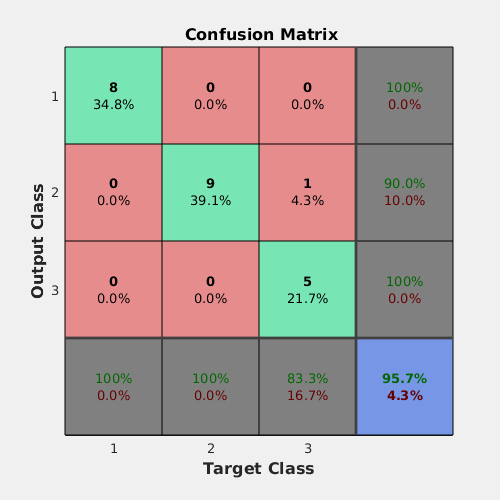

figure(3), plotconfusion(clasificacion_test,clasificacion_test_red);

# 4) Utiliza la red para clasificar una flor Iris en base a sus características

Con un ejemplar desconocido para la red (no utilizado durante su entrenamiento), ¿a qué clase pertenece realmente?

[flor_caracteristicas,clasificacion_flor]=obtener_ejemplar

flor_caracteristicas =     4.8000
    3.0000
    1.4000
    0.3000


clasificacion_flor =      1
     0
     0


tipo_flor(clasificacion_flor)

ans = "setosa"

flor_clasificacion_red=red_entrenada(flor_caracteristicas)

flor_clasificacion_red =     0.9979
    0.0021
    0.0000


tipo_flor(flor_clasificacion_red)

ans = "setosa"

# 5) Viendo algunas demos.

Vamos a repasar algunos conceptos que hemos visto durante clase. Para ello vamos a utilizar algunas demo muy útiles para la visualización de un proceso de entrenamiento.

## 5.1 Clasificación Lineal

En el siguiente hiperenlace encontrarás una demo muy útil para hacer

http://vision.stanford.edu/teaching/cs231n-demos/linear-classify/